First we are going to define the data path. The function is going to import every xlsx file in the designated folder.

path = 'Data/forcemap01/';

Usually the sampling frequency and other relevant information is stored in the data file. However, in this example, our FD curves are stored in xlsx files and do not contain such inforation. Therefore, we have to provide the sampling frequency. 

 f = 50000;

As mentioned in the manuscript, the method is not AFM exclusive and should work with any stress-strain relationship. The function written can handle stress-strain relationship and spherical indenter force distance curves. Since our data is coming from AFM, we are going to use spheriacal indenter and we have to let the function know. Likewise, we have to provide the probe tip radius.

 fd_check = 'fd';
 R = 35 * 1e-9;

`Calculating Relaxance`

This function does almost everything. Imports the data from files and calculates the relaxance. Returns relaxance, frequency axis in Hz, ln(r) and frequency axis in radians.

[Q,freq_axis,lnr,freq_axis_rad] = ...
    calculateQ(path,f,R,fd_check);

`Fitting to a Single Arm Generalized Maxwell Model`

Here we are going to fit our relaxance to a single arm Generalized Maxwell Model

Q_prefit = abs(real(Q)) -1i * (imag(Q));
abs_Q_prefit = abs(Q_prefit);
i_Q_prefit = imag(Q_prefit);
r_Q_prefit = real(Q_prefit);


[fitresult_mxwll, ~] = ...
    fitMaxwell_1arm(freq_axis_rad, abs(abs_Q_prefit), lnr);
[coeffs_mxwll] = coeffvalues(fitresult_mxwll);

G1 = coeffs_mxwll(2);
Ge = coeffs_mxwll(1);
tau = coeffs_mxwll(3);

Q_fit_maxwell = ...
    Ge + G1 - G1./...
    (1+tau * (1-exp(-0.075)*exp(-1i*freq_axis_rad)));

`Fitting to a Springpot Model`

Here we are going to fit our relaxance to Springepot Model

Q_cut = Q(freq_axis > (-1e-15));
Q_cut_abs = abs(Q_cut);
freq_axis_rad_cut = freq_axis_rad(freq_axis > (-1e-15));
freq_axis_cut = freq_axis(freq_axis > (-1e-15));


[fitresult_sprng, ~] = springpot_fit(freq_axis_rad_cut,Q_cut_abs, lnr);
[coeffs_sprng] = coeffvalues(fitresult_sprng);

C_beta = coeffs_sprng(1);
beta = coeffs_sprng(2);


Q_fit_spring = C_beta * ((1 - exp(-lnr)*exp(1i*freq_axis_rad)).^beta);

`Plotting Relaxance and Model Fits`

`Plotting real part of the relaxance. This coralates to storage behavior.`

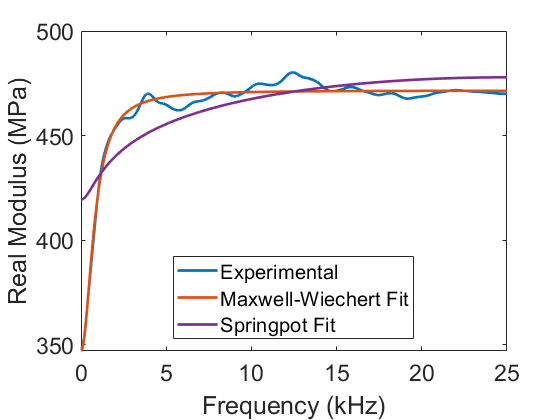

figure(1)
plot(freq_axis / 1000,abs(real(Q) * (1e-6)),'LineWidth',2)

xlim([0 f/(2 * 1000)])

xlabel('Frequency (kHz)')
ylabel('Real Modulus (MPa)')
set(gca,'fontsize', 17);


hold on
plot(freq_axis / 1000,abs(real(Q_fit_maxwell) * (1e-6)),'LineWidth',2)
plot(freq_axis / 1000,abs(real(Q_fit_spring) * (1e-6)),'LineWidth',2, ...
    'Color',[0.4940 0.1840 0.5560]);
hold off

legend('Experimental', 'Maxwell-Wiechert Fit', 'Springpot Fit',...
    'Location','Best');

`Plotting imaginary part of the relaxance. This coralates to storage behavior.`

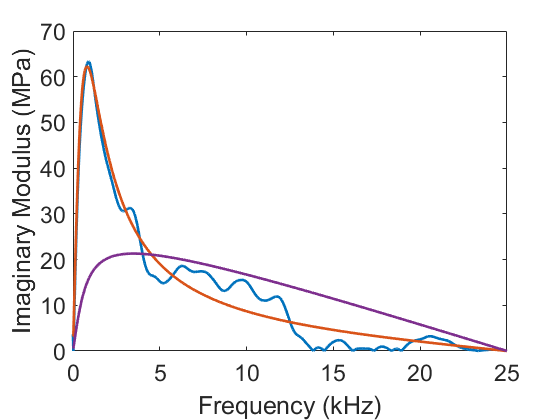

figure(2)
plot(freq_axis / 1000, abs(imag(Q))/ 1e6,'LineWidth',2)
hold on
%plot(freq_axis_cut / 1000,abs(imag(Q_fit)) / 1e6,'LineWidth',2)
hold off
y_lims = ylim;
ylim([0 y_lims(2)]);

xlim([0 f/(2 * 1000)])

xlabel('Frequency (kHz)')
ylabel('Imaginary Modulus (MPa)')
set(gca,'fontsize', 17);

hold on
plot(freq_axis / 1000,abs(imag(Q_fit_maxwell) * (1e-6)),'LineWidth',2)
plot(freq_axis / 1000,abs(imag(Q_fit_spring) * (1e-6)),'LineWidth',2, ...
    'Color',[0.4940 0.1840 0.5560]);
hold off

`Storage and Loss Modulus`

`Calculating the storage and loss modulus from the fits.`

Q_maxwell = Ge + G1 - G1./(1+tau * (1-exp(-1i*freq_axis_rad)));
Q_m_storage = abs(real(Q_maxwell));
Q_m_loss = abs(imag(Q_maxwell));

Q_spring = C_beta * ((1 - exp(1i*freq_axis_rad)).^beta);
Q_s_storage = abs(real(Q_spring));
Q_s_loss = abs(imag(Q_spring));

Now we are going to plot the storage and loss modulus

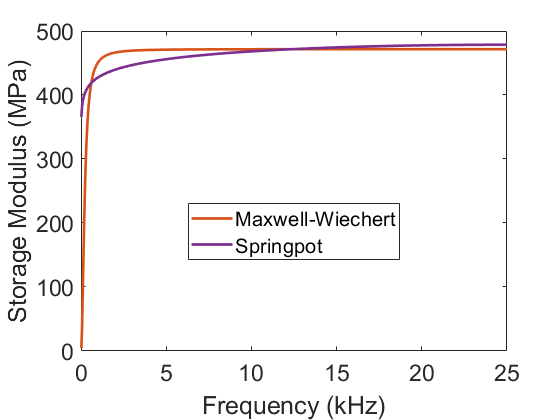

figure(3)
plot(freq_axis / 1000,Q_m_storage * (1e-6),'LineWidth',2, ...
    'Color', [0.8500 0.3250 0.0980]);
hold on
plot(freq_axis / 1000,Q_s_storage * (1e-6),'LineWidth',2, ...
    'Color',[0.4940 0.1840 0.5560]);
hold off
xlim([0 f/(2 * 1000)])

hold on

xlabel('Frequency (kHz)')
ylabel('Storage Modulus (MPa)')
set(gca,'fontsize', 17);

legend('Maxwell-Wiechert', 'Springpot',...
    'Location','Best');

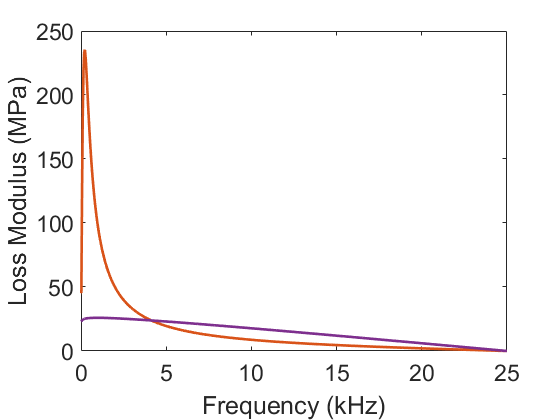


figure(4)
plot(freq_axis / 1000,Q_m_loss * (1e-6),'LineWidth',2, ...
    'Color', [0.8500 0.3250 0.0980]);
hold on
plot(freq_axis / 1000,Q_s_loss * (1e-6),'LineWidth',2, ...
    'Color',[0.4940 0.1840 0.5560]);
hold off
xlim([0 f/(2 * 1000)])


xlabel('Frequency (kHz)')
ylabel('Loss Modulus (MPa)')
set(gca,'fontsize', 17);